## Lab 2

Name: 

ID: 

### Task 1

Generate a LTSpice model of the RLC circuit.

Instructions:

Sample differencing op-amp configuration:

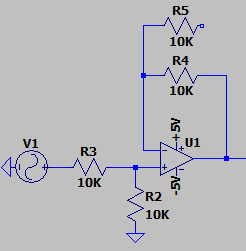

Sample buffering op-amp configuration:

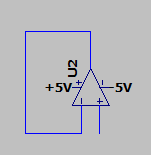

Sample RLC configuration:

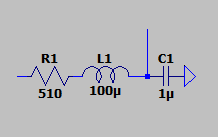

After you finish your model, run a 1 Vpp squarewave with a frequency of 75 Hz into the system. Sample configuration:

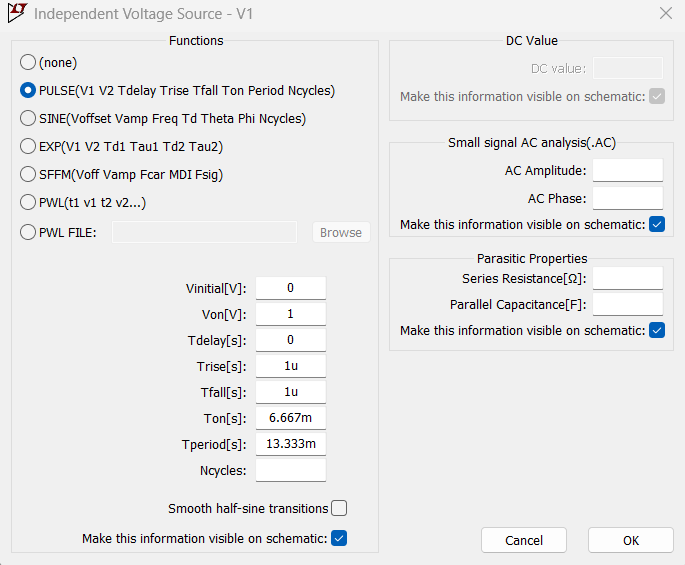

Your final output should look something like this - where the green trace is the square input:

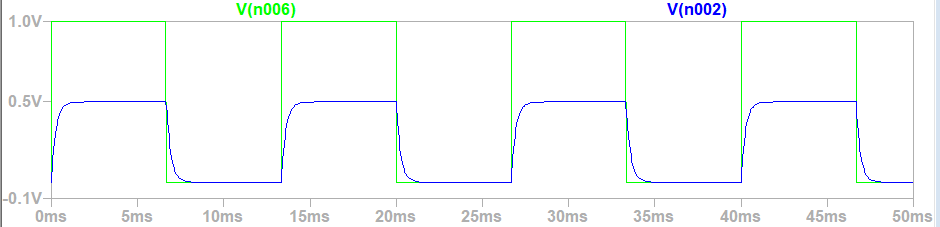

After you complete your model and generate the output, attach screenshots of the model and the output below:

#### Task 2

Rerun your Matlab script from last week, but with the values of R, L, and C changed to match your current components. How do the simulation and the real results differ?

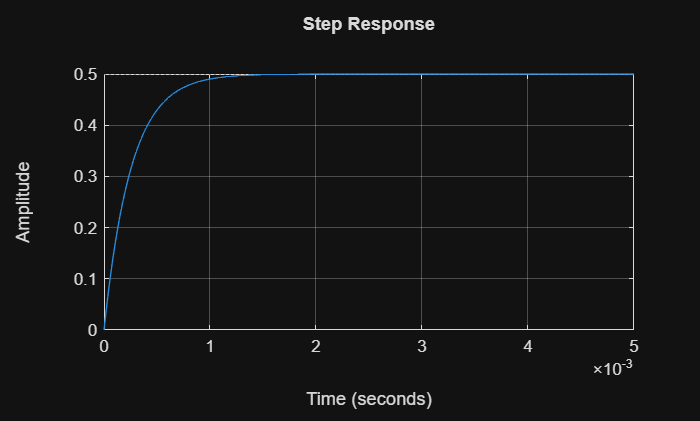

%% Parameters for the RLC circuit
R = 510;
L = 100/1e6;
C = 1/1e6;

numerator = 1;
denominator = [L, R, 1/C]*C;

%% Create the transfer function
sys = tf(numerator, denominator);
sys = feedback(sys, 1);

%% Plot the step response over 50 seconds
step(sys, 0.005);
title('Step Response');
grid on

#### Task 3

Try applying different signals to the input, such as sine, ramp, etc.

- How well does the output follow the input?

- Try using a larger resistor for R in your circuit. What happens?

- How does using a smaller resistor affect this?